clear all;close all;
mu_list=[5.5:0.01:8.5];
confidence=0.68;% better > 0.5
resolution=0.0001;
for j=1:length(mu_list)
    mu=mu_list(j);
    integral_core=@(x) P_mu(x,mu);
    success=0;b0=1.8;a0=0;i=1;
    while success==0
        y0=a0/2+b0/2;
        [x1,x2]=find_solution(mu,y0);
        integration=integral(integral_core,x1,x2);
        if 0%i>1 && abs(a0-b0)<1e-10
            %integration
            %success=1;
        elseif integration<(confidence-resolution)
            b0=y0;
        elseif integration>(confidence+resolution)
            a0=y0;
        else
            success=1;
            final_x1(j)=x1;
            final_x2(j)=x2;
        end
        i=i+1;
    end
end

## Plot

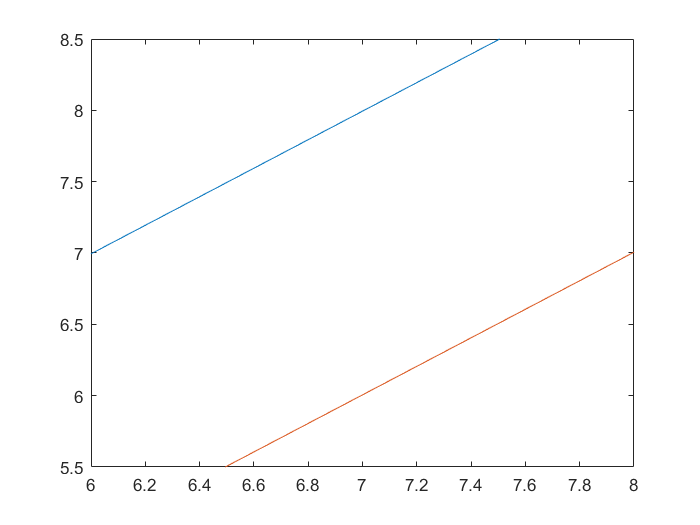

figure;
plot(final_x1,mu_list);hold on;
plot(final_x2,mu_list);
xlim([6 8])

% fplot(@(x) x-1,[0 10]);
% fplot(@(x) x+1,[0 10]);

function output=P_mu(x,mu)
    output=1/sqrt(2*pi).*exp(-(x-mu).^2./2);
end

function [x1,x2]=find_solution(mu,y0)
    if y0<=exp(-mu^2/2)
        x1=1/2*mu+1/mu*log(y0);
        x2=mu+sqrt(-2*log(y0));
    else
        x1=mu-sqrt(-2*log(y0));
        x2=mu+sqrt(-2*log(y0));
    end
end